# 02504 Exercise 08: Structured light

# Søren K. S. Gregersen, sorgre@dtu.dk, DTU Compute, March 2020

### Quick guide to a live script:

- CTRL+ENTER: Run section

- Function definitions: at the bottom of the document

- Figures do not open outside of the editor, but you can by pressing the small icon in the top right.

To see the matlab help, use search the documentation for Create Live Scripts in the Live Editor.

## **Calibrate your cameras:**

Start by calibration your cameras using the function stereoCalibrateCamera() defined in this document.

stereo_params = stereoCalibrateCamera('calib_images', 'SquareSize', 15);

Always check the reprojection error. 

err1 = vecnorm(stereo_params.CameraParameters1.ReprojectionErrors, 2, 2);
err2 = vecnorm(stereo_params.CameraParameters2.ReprojectionErrors, 2, 2);
errors = [err1, err2];
std(errors(:))

ans = 0.0901

mean(errors(:))

ans = 0.1560

## Load our data:

This section just load data and rectify. Use it to load/reload data into your program. I will take this opportunity to explain the images taken from our scanner.

The first two images taken in any sequence of a scan is a fully illuminated image and a dark image:

unrect_lit1 = imread('angel/frames0_0.png');
unrect_lit2 = imread('angel/frames1_0.png');
unrect_dark1 = imread('angel/frames0_1.png');
unrect_dark2 = imread('angel/frames1_1.png');

These serve to set a baseline for mimum and maximum intensities. Notice that these are unrectified, hence the prefix.

**Rectification (Optional):**

In some algorithms, rectification is optional. Since rectification is an interpolated method, there is a risk of introducing more errors. However, in our scanner this error is considered neglible. With rectified images, on the other hand, our algorthm becomes much easier to write. In your algorithm you can use the pre-rectified images.

[lit1, lit2] = rectifyStereoImages(unrect_lit1, unrect_lit2, stereo_params, 'OutputView', 'full');
[dark1, dark2] = rectifyStereoImages(unrect_dark1, unrect_dark2, stereo_params, 'OutputView', 'full');

After the two first images, we have a series of images that correspond to the structured light encoding scheme. In case of phase shifting, we have two sequences: the primary sequence and the cue sequence.

[H, W, ~] = size(lit1);
seq1_primary = zeros([8 H W]);
seq2_primary = zeros([8 H W]);
seq1_cue = zeros([8 H W]);
seq2_cue = zeros([8 H W]);

The primary sequence encodes the primary phase, which is the wrapped synthetic phase. The cue sequence encodes the cue phase, which is only used to unwrap the primary phase. We have used 8 images to resolve both the primary and secondary phase. 

for i = 1:8
    f1 = ['angel/frames0_' int2str(i + 1) '.png'];
    f2 = ['angel/frames1_' int2str(i + 1) '.png'];
    I1 = rgb2gray(imread(f1));
    I2 = rgb2gray(imread(f2));
    [J1, J2] = rectifyStereoImages(I1, I2, stereo_params, 'OutputView', 'full');
    seq1_primary(i, :, :) = J1;
    seq2_primary(i, :, :) = J2;
end
for i = 1:8
    f1 = ['angel/frames0_' int2str(i + 1 + 8) '.png'];
    f2 = ['angel/frames1_' int2str(i + 1 + 8) '.png'];
    I1 = rgb2gray(imread(f1));
    I2 = rgb2gray(imread(f2));
    [J1, J2] = rectifyStereoImages(I1, I2, stereo_params, 'OutputView', 'full');
    seq1_cue(i, :, :) = J1;
    seq2_cue(i, :, :) = J2;
end

Finally, we could assume, until further processing, that all of our pixels are equally valid. We do this by introducing a mask. The mask has the same dimensions as the image, and where the mask is 1 the pixel is valid; where it is zero the pixel is not valid.

mask1 = ones([H, W]);
mask2 = ones([H, W]);

This is also where you can precondistion your boundaries. For example, assume boundary pixels are invalid.

mask1(1, :) = 0;
mask1(end, :) = 0;
mask1(:, 1) = 0;
mask1(:, end) = 0;
mask2(1, :) = 0;
mask2(end, :) = 0;
mask2(:, 1) = 0;
mask2(:, end) = 0;

When the mask is set correctly, you should see white rectangles with black borders. (You might need to zoom in to see them all.)

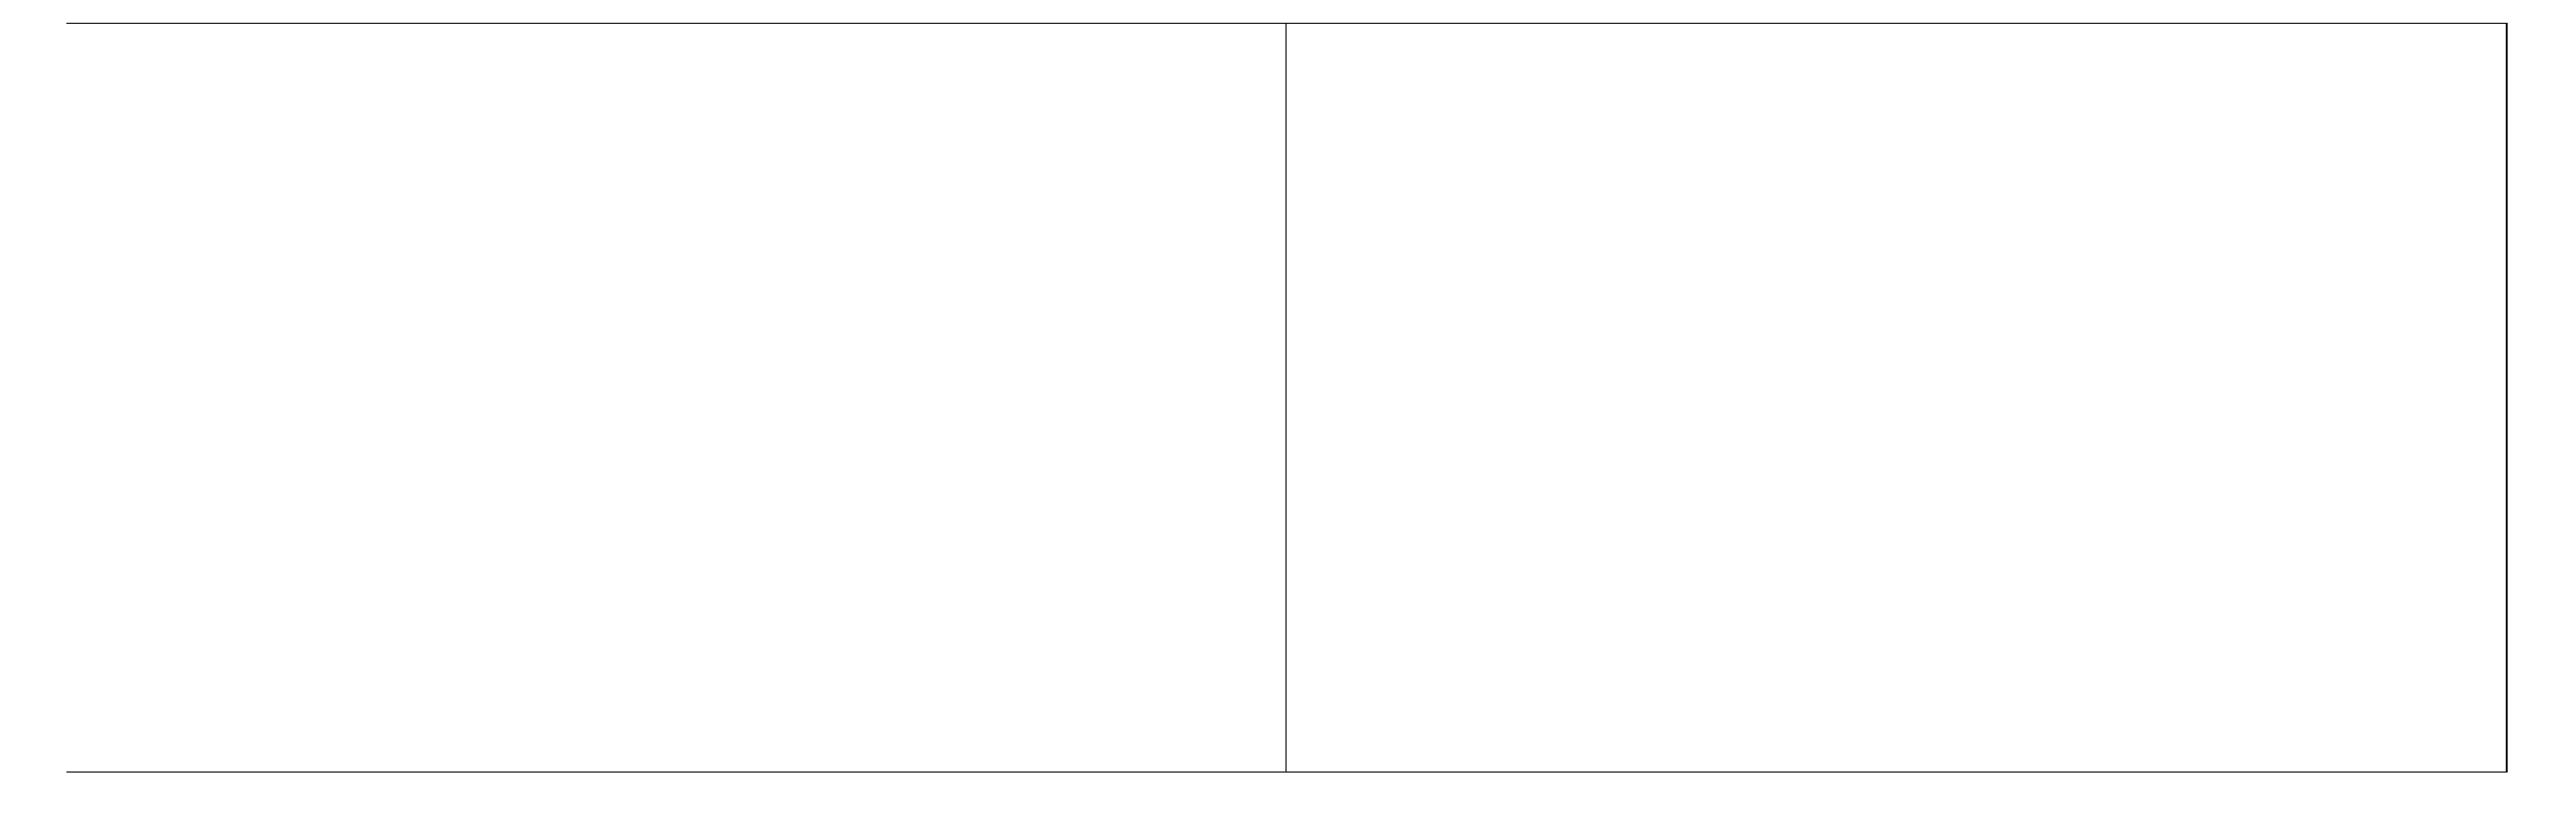

figure; imshowpair(mask1, mask2, 'montage')

## Pixel confidence:

Given a set of standard cameras, you should never trust values near the extremes: the minumum and maximum. On most cameras values are 1 byte integers between 0 and 255. The tolerance depends heavily on the quality of the cameras, but in general we find good performance on our cameras by excluding the top and bottom 10% of the range.

adjusted1 = rgb2gray(lit1 - dark1);
adjusted2 = rgb2gray(lit2 - dark2);

min_tol = 0.1 * 255;
max_tol = 0.9 * 255;

% Notice the logical and '&', which combines the multiple conditions.
mask1 = mask1 & (adjusted1 > min_tol) & (adjusted1 < max_tol); 
mask2 = mask2 & (adjusted2 > min_tol) & (adjusted2 < max_tol);

Plot the pixel masks to view the valid areas

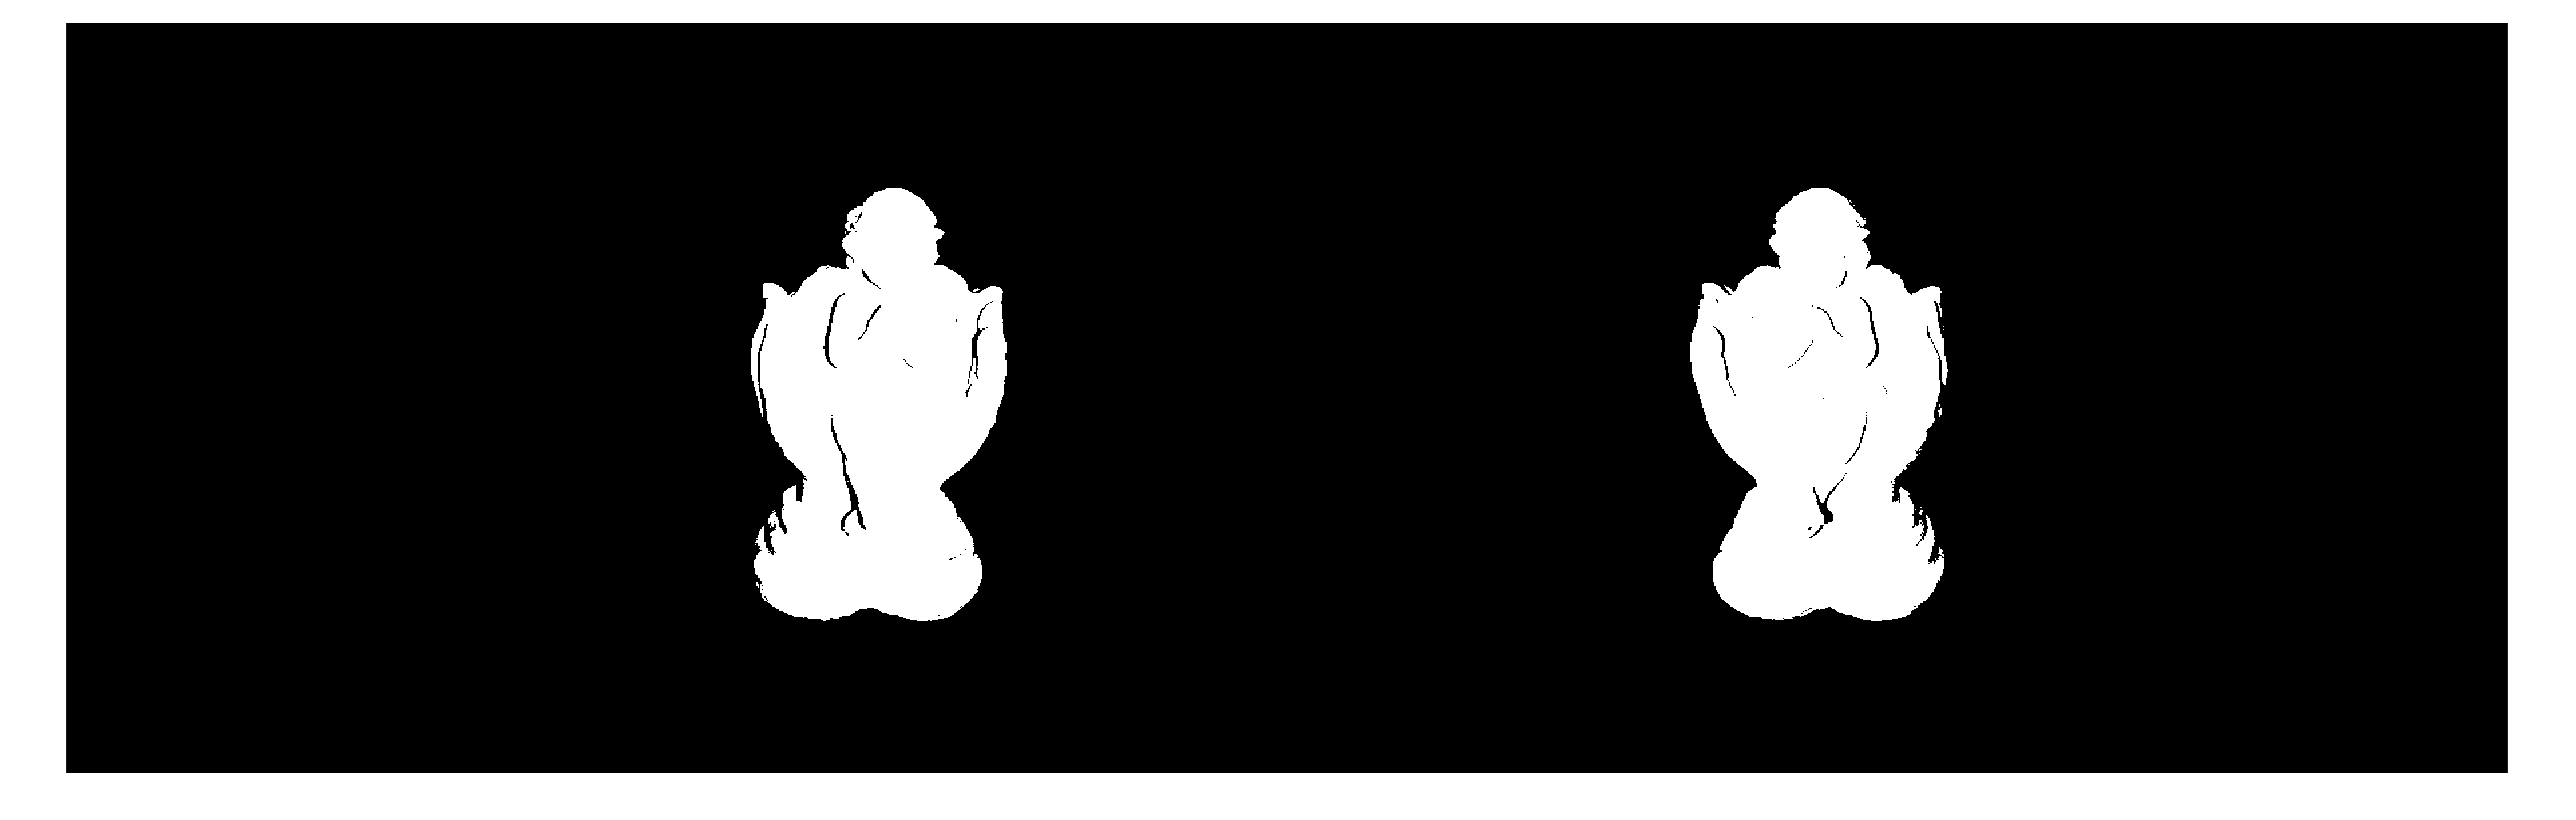

figure; imshowpair(mask1, mask2, 'montage')

All white area is the valid pixels. Notice how this is very effective at removing the black background.

## Decoding phases:

Decoding can be done easily using the Fourier transform and the heterodyne principal. Find the implementation of the decoding inside the function decodePhase().

phase1 = decodePhase(seq1_primary, seq1_cue);
phase2 = decodePhase(seq2_primary, seq2_cue);

Plot the phase with the pixel masks to view the valid areas

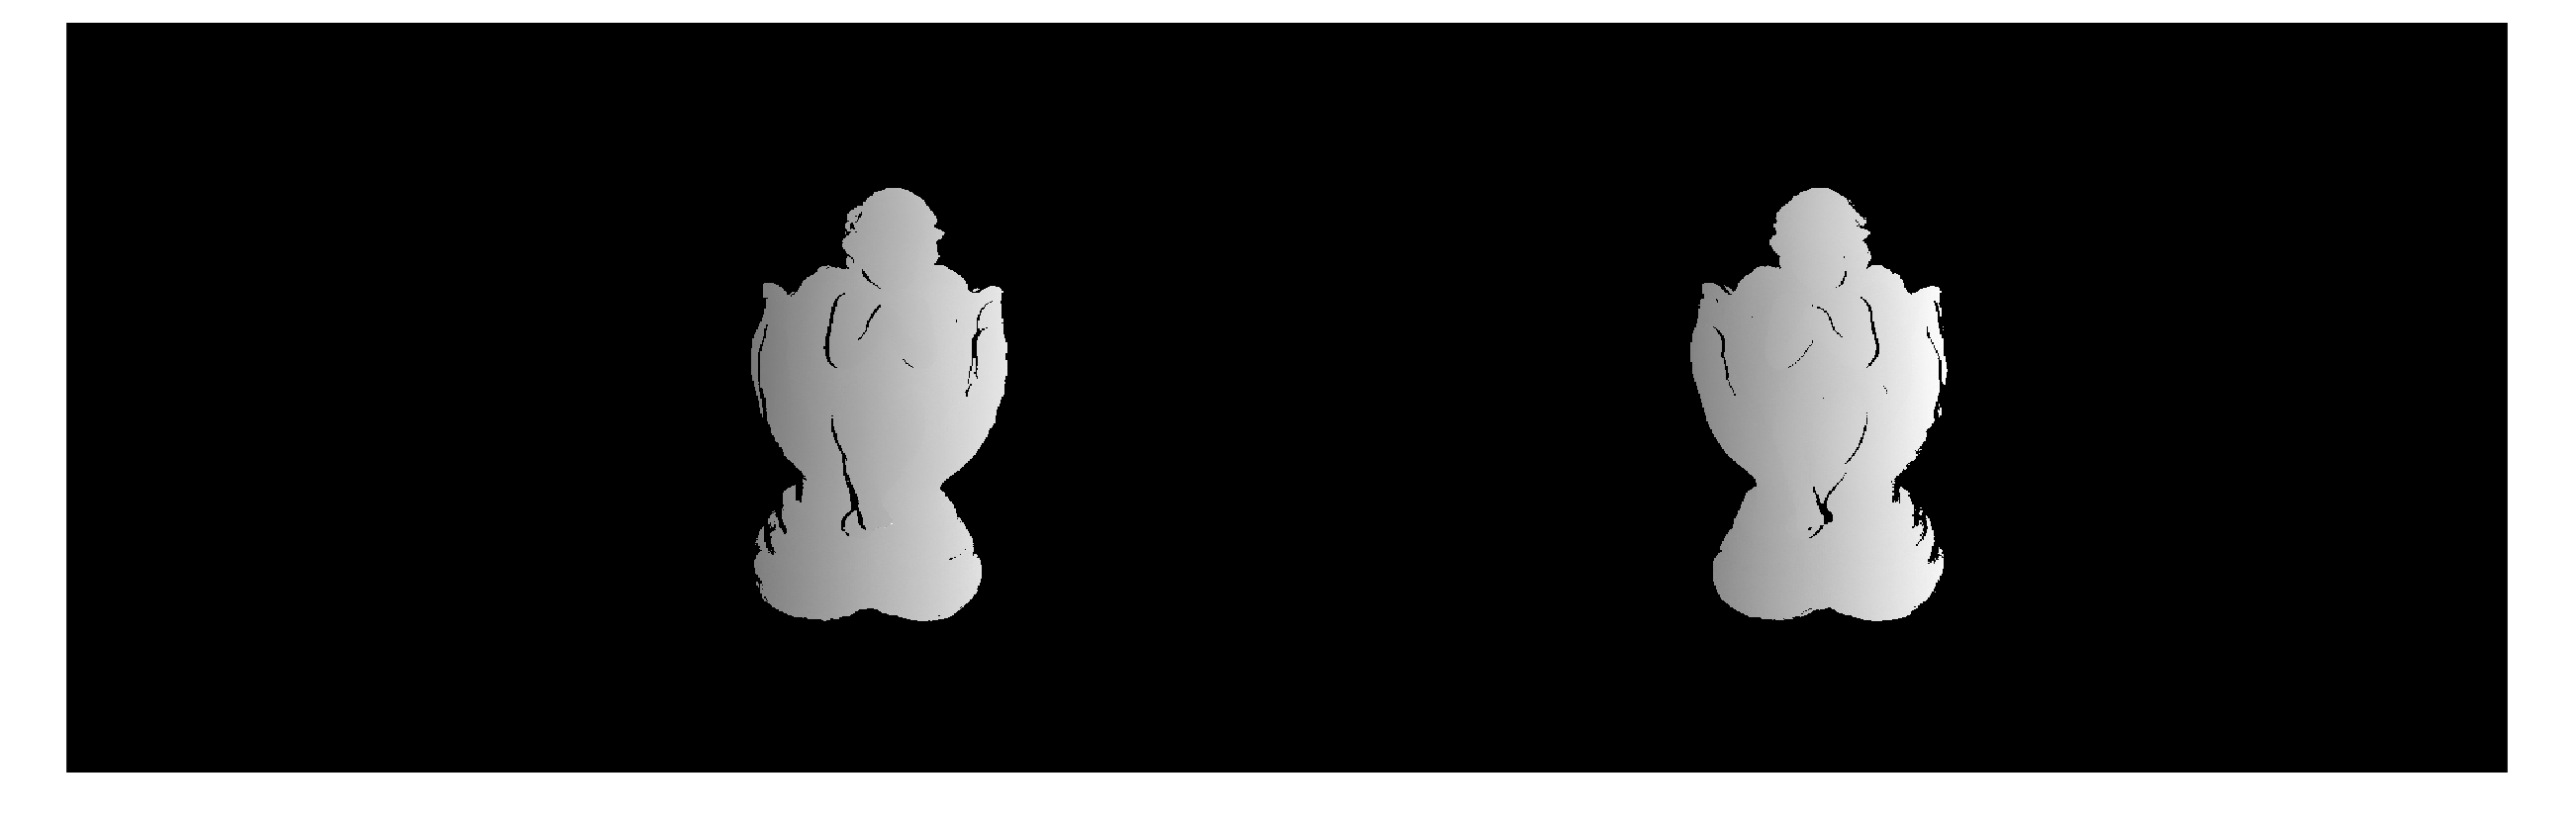

figure; imshowpair(phase1 .* mask1, phase2 .* mask2, 'montage')

## Find correspondence:

Since we know that our images are rectified, we know that the epipolar lines are alinged horizotally. And so the correspondence problem between images becomes a simple loop of line-correspondence problems. Finish the registerContinuous().

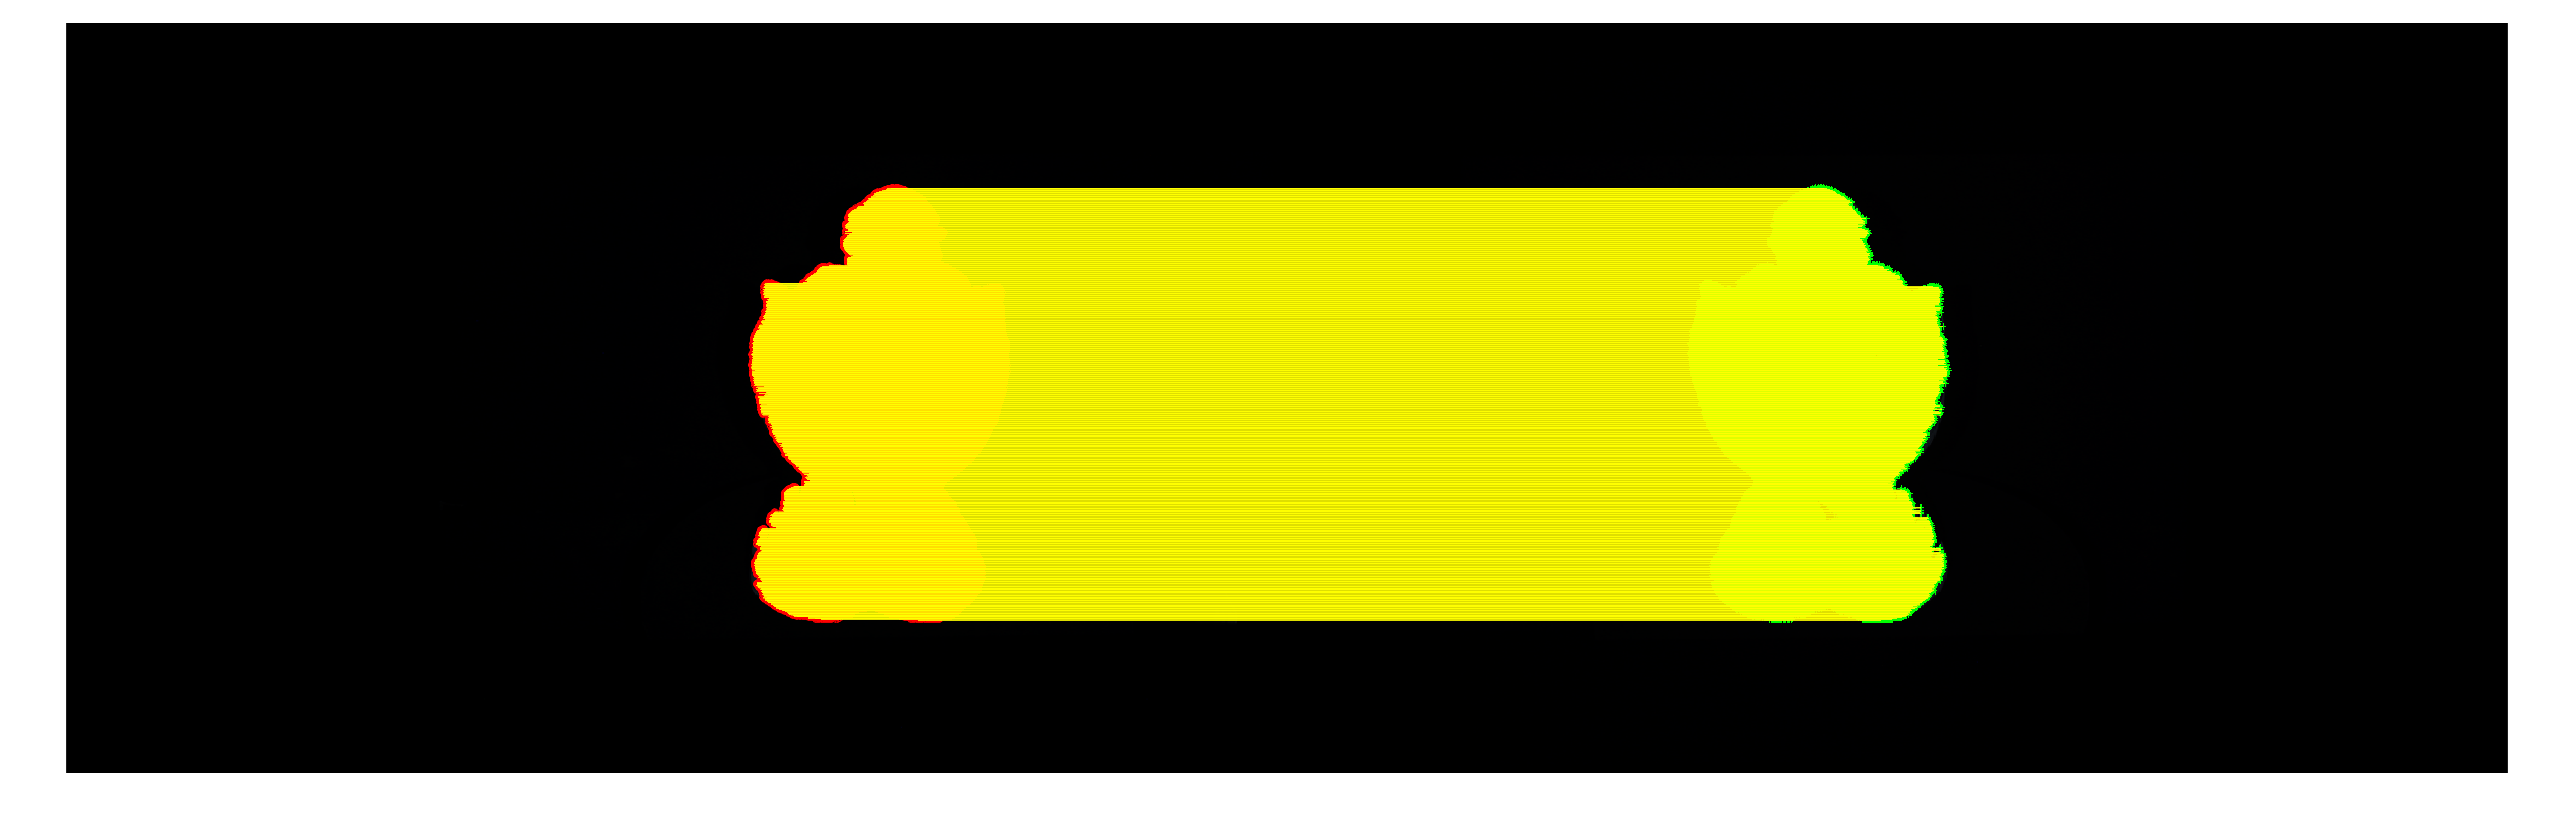

[q1, q2] = registerContinuous(phase1, phase2, mask1, mask2);

showMatchedFeatures(lit1, lit2, q1, q2, 'montage');

## Triangulation:

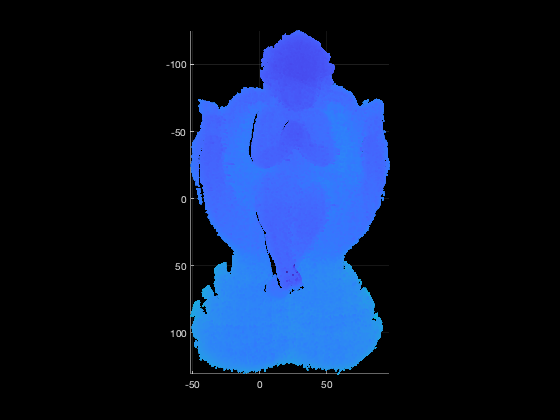

% Get the original camera matrices
P1 = cameraMatrix(stereo_params.CameraParameters1, eye(3), zeros(1, 3))';
P2 = cameraMatrix(stereo_params.CameraParameters2, stereo_params.RotationOfCamera2, stereo_params.TranslationOfCamera2)';

% In case of rectification:
% Do not use this if you loaded the pre-rectified images during
% your camera calibration. This method uses, in fact,
% undocumented features. I don't know when it will stop working.
H1 = stereo_params.toStruct().RectificationParams.H1';
H2 = stereo_params.toStruct().RectificationParams.H2';
origin = [0 0];
origin(1) = stereo_params.toStruct().RectificationParams.XBounds(1) - 1;
origin(2) = stereo_params.toStruct().RectificationParams.YBounds(1) - 1;
% Transform the real camera porjections into the rectified cameras:
% to: translation of origin:
to = [1 0 -origin(1); 0 1 -origin(2); 0 0 1];
P1 = to * H1 * P1;
P2 = to * H2 * P2;

Q = triangulate(q1, q2, P1', P2'); % Matlab uses a transposed version of the projection matrix
ptCloud = pointCloud(Q);
pcshow(ptCloud); view([0 -90])

You can also look at the .ply file, which contains the same point cloud.

pcwrite(ptCloud,'angel.ply','PLYFormat','binary');

## Functions:

function stereo_params = stereoCalibrateCamera(calib_folder, varargin)
    % calibrates a stereo camera system, returns a stereoParameters object
    %
    % Inputs:
    %     - calib_folder: string path to folder with calibration images
    % Optional parameters:
    %     - 'SquareSize': size of checkerboard squares, a positive number
    % Output:
    %     - stereo_params: stereoParameters, see help stereoParameters
    
    % Parsing the optional parameters:
    %     This is purely a matlab thing. It allows us to call the function
    %     like stereoCalibrateCamera(calib_folder) or
    %     stereoCalibrateCamera(calib_folder, 'SquareSize', size). The
    %     default value for the square size is 1.
    p = inputParser;
    error_msg = 'Square size must be positive, scalar, and numeric.';
    valid_size_fn = @(x) assert(isnumeric(x) && isscalar(x) && (x > 0), error_msg);
    addParameter(p,'SquareSize', 1, valid_size_fn);
    parse(p,varargin{:});
    square_size = p.Results.SquareSize;
    
    % Search for image files
    im1_files = dir(fullfile(calib_folder, 'frame0_*.png'));
    im2_files = dir(fullfile(calib_folder, 'frame1_*.png'));
    % Get their full path strings
    im1_files = fullfile({im1_files(:).folder},{im1_files(:).name});
    im2_files = fullfile({im2_files(:).folder},{im2_files(:).name});
    
    % The easiest way to generate a stereoParameters object is to use the
    % estimateCameraParameters(). If you use your own calibration technique,
    % you should fill out the values in stereoParameters yourself.
    
    % Get the image size
    I = imread(im1_files{1});
    image_size = [size(I, 1),size(I, 2)];

    % Detect checkerboards in images
    [p2D, board_size] = detectCheckerboardPoints(im1_files, im2_files);
    p3D = generateCheckerboardPoints(board_size, square_size);
    stereo_params = estimateCameraParameters(p2D, p3D, 'ImageSize', image_size);
end

function phase = decodePhase(primary, cue)
    % calculates an unwraped synthetic phase.
    %
    % Inputs:
    %     - primary: 3D image array size [N, H, W]
    %     - cue: 3D image array size [N, H, W]
    % Outputs:
    %     - phase: 2D image array of the synthetic phase [H, W]
    
    F_primary = fft(primary);
    F_primary = F_primary(1:end/2, :, :); % skip aliasing (not interesting)
    F_cue = fft(cue);
    F_cue = F_cue(1:end/2, :, :); % skip aliasing (not interesting)
        
    channel = 2; % I.e. a single period in the time sequence
    primary = squeeze(angle(F_primary(channel, :, :)));
    cue = squeeze(angle(F_cue(channel, :, :)));
    
    phase = mod(primary - cue, 2 * pi);
   
    % Now we also have chance to validate pixel from the Fourier spectrum. We know
    % that our signal must mostly occupy the first (DC) channel and the second (1-period)
    % channel. The rest is noise, and we should try not to use a signal with too high
    % signal-to-noise ratio. You could implement this your self as an
    % exercise.
end

function [q1, q2] = registerContinuous(code1, code2, mask1, mask2)
    % returns matched feature points (q1 and q2)
    %
    % Inputs:
    %     - code1, code2: 2D code images from a stereo set up.
    %     - mask1, mask2: 2D logical arrays with valid pixels.
    % Output:
    %     - q1, q2: [m-by-2] array of matches in im1 and im2, respectively.
        
    % assume a maximum point count (not strict, but allows for faster
    % code operation).
    max_point_guess = 500000;
    q1 = zeros(max_point_guess, 2);
    q2 = zeros(max_point_guess, 2);
    i = 0;
    
    % Skip masked rows and columns in code1 and code2.
    % This is not neccesary, but it makes the loop much smaller by
    % skipping masked rows and columns.
    [rows1, cols1] = find(mask1);
    [rows2, cols2] = find(mask2);
    rows = [rows1; rows2]; % Remember, rows are common epiloar lines
    % Turned into min-max ranges.
    rows = min(rows):max(rows);
    cols1 = min(cols1):max(cols1);
    cols2 = min(cols2):max(cols2);
    
    for r = rows
        % we loop over all (valid) rows, and match the entire row in one go (faster code!)
        x = code1(r, cols1)'; % The code1 we wish to match ==> x
        left = code2(r, cols2(1:end-1)); % The left side of code2
        right = code2(r, cols2(2:end)); % The right side of code2
        
        % Any match has the code between the left and right sides. Notice
        % that I match for either left < x <= right or left >= x > right.
        % This enables both positive and negative gradients.
        match = ((left < x) & (x <= right)) | ((left >= x) & (x > right));
        % Obviously, the values cannot be masked.
        match = match & mask1(r, cols1)' & mask2(r, cols2(1:end-1)) & mask2(r, cols2(2:end));
        
        [c1, c2] = find(match); % Now we loop through matches.
        for j = 1:length(c1)
            i = i + 1; % Now we have one more match.
            
            q1(i, 1:2) = [c1(j) + cols1(1) - 1, r];
            q2(i, 1:2) = [c2(j) + cols2(1) - 1, r];
            % Notice that we just use the left-side pixel as the match. In
            % fact, we should use a subpixel value somewhere between the
            % left and the right value.
            
            phase2_dist = right(c2(j)) - left(c2(j)); % Phase distance between left and right
            phase1_dist = x(c1(j)) - left(c2(j));     % Phase distance between x and left
            subpix_dist = phase1_dist / phase2_dist;  % Distance in pixels
       
            q2(i, 1) = q2(i, 1) + subpix_dist; % Adding the distance
            
        end
        
        % Challenge exercise: Right now, we actually allow multiple matches
        % of the same pixel in one image. This is obviously a mistake, but
        % a rare one. Since there is no way of telling which match is the
        % correct match, we should in fact skip all multiple matched
        % pixels. Your challenge is to fix the above code to remove the
        % duplicates.
    end
    
    q1 = q1(1:i, :); % Shorten the matches to the right size.
    q2 = q2(1:i, :);
end